clear variables

fname = 'Job-3-1kg-size10.inp';
[Nodes, Elements] = Readmesh(fname);
NodeCount = size(Nodes,1) ;     % 节点个数
ElementCount= size(Elements,1); % 单元个数
ElementNodeCount=8;             % 每个单元节点数

load Project_1_ForceIdentification\Data\experimentAIPlate\7075Al_size10_0714.mat
 
K = globalStiffness;
M = globalMass;

M_Shell = diag(sum(M));

[dimx,dimy] = find(K>10e30);
K_Shell = K;

K_Shell(sub2ind(size(K_Shell),dimx,dimy)) = K(sub2ind(size(K),dimx,dimy))*10e-29;

Dof = 3;
Forces = [26 2;42 2;15 2;];
ConDOF = Dof*(Forces(:,1)-1)+Forces(:,2);       % 计算外力自由度编号
Obs = [22 2;3 2;45 2;46 2;40 2;39 2];
ObsDOF = Dof*(Obs(:,1)-1)+Obs(:,2);             % 计算控制点自由度编号

opt = [];

inputDim = size(ConDOF,1);
outputDim = size(ObsDOF,1);
opt.damp.alpha = 0.004;
opt.damp.belta = 0.001;

dim = size(M_Shell,1);
inputsize = size(ConDOF,1);
outputsize = size(ObsDOF,1);

DD = zeros(dim,inputsize);

for i = 1:inputsize
    DD(ConDOF(i,:),i) = 1;
end

C = zeros(outputsize,dim);
for i = 1:outputsize
    C(i,ObsDOF(i,:)) = 1;
end

D = 0.004*K_Shell+0.001*M_Shell;

sys = second2first(M_Shell,D,K_Shell,DD,C);
[A,B,C,D,E] = dssdata(ss(sys));

sysDis = c2d(dss2ss(sys),0.05);

[sysr, V, W, s0] = irka(sys,6);
sysrDis = c2d(dss2ss(sysr),0.05);

% 如果使用该方式进行运算，则变为直接馈通系统？？
sysSparss = sparss(A,B,C,[],E);
sysDisSparss = c2d(sysSparss,0.05,'tustin');
sysFull = full(sysDisSparss);

ans =     0.8157    0.7902    0.7649
    0.7649    0.7902    0.8157
    0.5332    0.5138    0.4945
    0.4945    0.5138    0.5332
    0.2865    0.2734    0.2603
    0.2603    0.2734    0.2865


sysrDisTursin = c2d(dss2ss(sysr),0.05,'tustin');
sysrDisTursin.D

ans =     0.7903    0.7900    0.7901
    0.7903    0.7905    0.7904
    0.5139    0.5136    0.5138
    0.5139    0.5140    0.5139
    0.2734    0.2733    0.2733
    0.2734    0.2736    0.2735


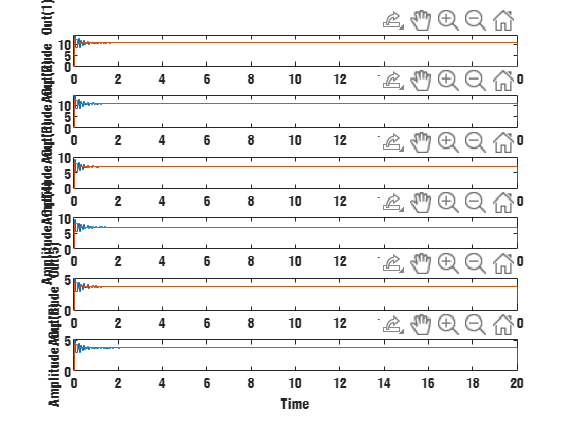

figure;
% u = @(t) sin(t) * ones(3, 1);
u = @(t)[0;10;0];
opts = [];
opts = struct('InputFcn', u, 'TimeRange', 20);
ml_dt_dss_simulate(sysFull,opts);
hold on
ml_dt_dss_simulate(sysrDis,opts);

sysFullDis = dss2ss(sysFull);

% 第一步响应有所区别，但是稳态响应基本没有任何区别
sysFullDis.C*sysFullDis.B*[0;10;0]+sysFullDis.D*[0;10;0]

ans =     0.1131
    0.1132
    0.0315
    0.0315
   -0.0040
   -0.0040


sysrDis.C*sysrDis.B*[0;10;0]+sysrDis.D*[0;10;0]

ans =    12.5657
   12.5751
    8.2543
    8.2615
    4.4411
    4.4459


sysDis.B*[0;10;0]

sysrDis.C

aaa = V*sysrDis.B*[0;10;0] - Uall;
figure;
plot(aaa(1:3240))

sysReduced = dss2ss(sysr);
sysReducedDis = c2d(sysReduced,0.05);
Ar = sysReducedDis.A;
Br = sysReducedDis.B;
Cr = sysReducedDis.C;

Uall = V*Br*[0;10;0];
U = Uall(1:3240,1);
max(U)

figure;
spy(sysDisSparss)

sysDisSparss.C*full(sysDisSparss.B)*[0;10;0]+full(sysDisSparss.D)*[0;10;0]

sysReduced = dss2ss(sysr);
sysReducedDis = c2d(sysReduced,0.05);
Ar = sysReducedDis.A;
Br = sysReducedDis.B;
Cr = sysReducedDis.C;

Uall = sysDis.B*[0;10;0];
U = Uall(1:3240,1);
max(U)

sysFullReal = dss2ss(sysFull);

figure
tic
plotContourPart(Nodes,Elements,U,U(2:3:end),1,0,15);%U3方向位移：y
toc

sysSS = sss(sysFull)

syscon = ss(sysr);
syscon.Ts = 0.05;

figure;
u = @(t) sin(t) * ones(3, 1);
opts = [];
opts = struct('InputFcn', u, 'TimeRange', 20);
ml_ct_dss_simulate_ie(ss(sys),ss(sysr),opts);


AAA = ss(sysr_sysSS_tbr);
AAA.Ts = 0.05;
figure;
u = @(t) sin(t) * ones(3, 1);
opts = [];
opts = struct('InputFcn', u, 'TimeRange', 20);
ml_ct_dss_simulate_ie(ss(sys),AAA,opts);


figure;
u = @(t) sin(t) * ones(3, 1);
opts = [];
opts = struct('InputFcn', u, 'TimeRange', 20);
ml_dt_dss_simulate(full(sysDisSparss),opts);

[sysr, V, W] = irka(sysSS,6);

figure;
u = @(t) sin(t) * ones(3, 1);
opts = [];
opts = struct('InputFcn', u, 'TimeRange', 20);
ml_dt_dss_simulate(sysFull,syscon,opts);

% opts = [];
% opts.StoreProjection = 1;
% [sysrModal, infoModal] = ml_dt_dss_mt(sysFull,opts);

opts = [];
opts.Order = {6,7,8,9,10};
opts.OrderComputation = 'order';
opts.FreqRange = [0,100];
[sysflbt,info] = ml_ct_dss_flbt(ss(sys),opts);

figure;
u = @(t) sin(t) * ones(3, 1);
opts = [];
opts = struct('InputFcn', u, 'TimeRange', 20);
ml_ct_dss_simulate_ie(sysflbt{1},opts);

% 使用这两种方法离散化没啥区别